# Exchange Data with ROS Publishers and Subscribers

The primary mechanism for ROS nodes to exchange data is sending and receiving *messages*. Messages are transmitted on a *topic,* and each topic has a unique name in the ROS network. If a node wants to share information, it uses a *publisher* to send data to a topic. A node that wants to receive that information uses a *subscriber* to that same topic. Besides its unique name, each topic also has a *message type*, which determines the types of messages that are capable of being transmitted under that topic.

This publisher and subscriber communication has the following characteristics:      

- Topics are used for many-to-many communication. Many publishers can send messages to the same topic and many subscribers can receive them.

- Publishers and subscribers are decoupled through topics and can be created and destroyed in any order. A message can be published to a topic even if there are no active subscribers.

The concept of topics, publishers, and subscribers is illustrated in the figure:

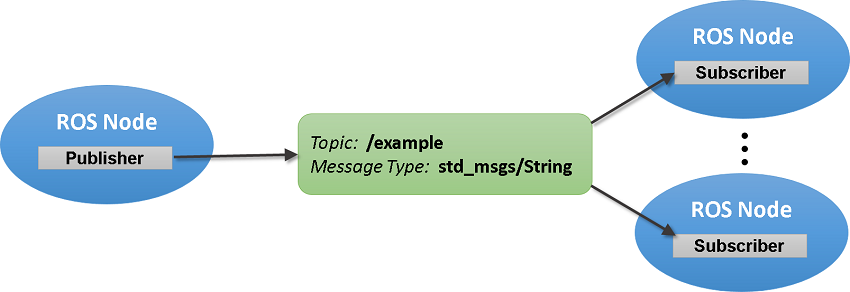

This example shows how to publish and subscribe to topics in a ROS network. It also shows how to:

- Wait until a new message is received

- Use callbacks to process new messages in the background

Prerequisites: [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a),  [Connect to a ROS Network](docid:ros_ug.mw_d625a603-7f37-4925-9470-2de734937434)

## Subscribe and Wait for Messages

Start the ROS master in MATLAB® using the [`rosinit`](docid:ros_ref.bupf5_j_1) command.

rosinit

Create a sample ROS network with several publishers and subscribers using the provided helper function `exampleHelperROSCreateSampleNetwork`.

exampleHelperROSCreateSampleNetwork

Use [`rostopic`](docid:ros_ref.bupf5_j_14)` list` to see which topics are available.

rostopic list

Use `rostopic info` to check if any nodes are publishing to the `/scan` topic. The command below shows that `node_3` is publishing to it.

rostopic info /scan

Use [`rossubscriber`](docid:ros_ref.bupf5_j_9) to subscribe to the `/scan` topic. If the topic already exists in the ROS network (as is the case here), `rossubscriber` detects its message type automatically, so you do not need to specify it. Use messages in struct format for better efficiency.

laser = rossubscriber("/scan","DataFormat","struct");
pause(2)

Use [`receive`](docid:ros_ref.buqbyro) to wait for a new message. (The second argument is a time-out in seconds.) The output `scandata` contains the received message data.

scandata = receive(laser,10)

Some message types have visualizers associated with them. For the LaserScan message, [`plot`](docid:ros_ref.buqbjtl) plots the scan data. The `MaximumRange` name-value pair specifies the maximum plot range.

figure
rosPlot(scandata,"MaximumRange",7)

## Subscribe Using Callback Functions

Instead of using [`receive`](docid:ros_ref.buqbyro) to get data, you can specify a function to be called when a new message is received. This allows other MATLAB code to execute while the subscriber is waiting for new messages. Callbacks are essential if you want to use multiple subscribers.

Subscribe to the `/pose` topic, using the callback function `exampleHelperROSPoseCallback`.

robotpose = rossubscriber("/pose",@exampleHelperROSPoseCallback,"DataFormat","struct")

One way of sharing data between your main workspace and the callback function is to use global variables. Define two global variables `pos` and `orient`.

global pos
global orient

The global variables `pos` and `orient` are assigned in the  `exampleHelperROSPoseCallback` function when new message data is received on the `/pose` topic.

Wait for a few seconds to make sure that the subscriber can receive messages. The most current position and orientation data will always be stored in the `pos` and `orient` variables.

pause(2) 
pos
orient

If you type in `pos` and `orient` a few times in the command line, you can see that the values are continuously updated.

Stop the pose subscriber by clearing the subscriber variable

clear robotpose

*Note*: There are other ways to extract information from callback functions besides using globals. For example, you can pass a handle object as additional argument to the callback function. See the [Callback Definition](docid:creating_plots.bt_h1z8) documentation for more information about defining callback functions.

## Publish Messages

Create a publisher that sends ROS string messages to the `/chatter` topic (see [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36)).

chatterpub = rospublisher("/chatter","std_msgs/String","DataFormat","struct")
pause(2) % Wait to ensure publisher is registered

Create and populate a ROS message to send to the `/chatter` topic.

chattermsg = rosmessage(chatterpub);
chattermsg.Data = 'hello world'

Use `rostopic list` to verify that the `/chatter` topic is available in the ROS network.

rostopic list

Define a subscriber for the `/chatter` topic.  `exampleHelperROSChatterCallback` is called when a new message is received and displays the string content in the message.

chattersub = rossubscriber("/chatter",@exampleHelperROSChatterCallback,"DataFormat","struct")

Publish a message to the `/chatter` topic. The string is displayed by the subscriber callback.

send(chatterpub,chattermsg)
pause(2)

The `exampleHelperROSChatterCallback` function was called as soon as you published the string message.

## Shut Down ROS Network

Remove the sample nodes, publishers, and subscribers from the ROS network. Clear the global variables `pos` and `orient.`

exampleHelperROSShutDownSampleNetwork
clear global pos orient

Shut down the ROS master and delete the global node.

rosshutdown

## Next Steps

- To learn more about how ROS messages are handled in MATLAB, see [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36) and [Work with Specialized ROS Messages](docid:ros_ug.mw_f993bbbe-25de-434f-bfd0-e5243256b23c).

- To explore ROS services, refer to [Call and Provide ROS Services](docid:ros_ug.mw_70dbf089-5821-4e67-b96f-f659aea10c0c).

*Copyright 2014-2021 The MathWorks, Inc.*